UNIVERSITY OF RWANDA, 

COLLEGE OF SCIENCE AND TECHNOLOGY, 

SCHOOL OF ENGINEERING, EEE DEPARTMENT

**Research Project: **

**Implementation of a Real-time Manuscript Scanner Software for Handwritten Lecturing Digitization.**

Group Members and Registration numbers:

- HABIYAREMYE NTWALI JANVIER: 218007332

- MALIZA CONSTANTINE: 218005312

- MBONIMPA PACOME SIMON: 218000124

# Report: Limitation Issues, Conclusion and Recommendations.

## FRAME RATE RELATED ISSUES AND CODE OPTIMIZATION.

As it is mentioned in the introduction, the goals of this project were set with an envision that it will provide an new alternative for digitized lecturing. Therefore, the time efficiency of the developed algorithms should match with real-time constraints of handwritting. To tackle with this challenge of frame rate determination, we referred to the data reported in a forensic related research paper **[R. A. Hardcastle and C. J. Matthews, “Speed of writing,” *****Journal of the Forensic Science Society*****, vol. 31, no. 1, pp. 21–29, Jan. 1991. ]**. The objective of that research was to determine the highest speed of handwritting that can be achieved by a person, from a selected sample of people. As it was reported, In undisputed police interview records, the highest speeds observed fell in the range 120–155 characters per minute. By conversion, that range is equivalent to about 2 - 2.58 characters per second. For our case, the targeted frame rate was to be set such that it would at least exceed the highest writting speed expected. Therefore, all the parameters used in the program were tuned so as to match an output frame rate of at least 3 frames per second, for a convenient image resolution, which by experimentation was found to be 2 megapixels.That frame rate was achieved on a computer with an I7 processor of 2.4 GHz clock. This means that the frame rate would increase if lower resolutions were used, but that would sacrifice the image quality. 

% load matlab.mat
rateTest
title("Average frame rate Against Different Image Resolutions")
xlabel("Resolution (megapixels)")
ylabel("Average Frames per Second")

Regarding the code optimization challenge, we had to rely on MATLAB programming language's syntax. One of the consulted resources suggests that we had to consider two important approaches for MATLAB code optimization: preallocating arrays and vectorizing loops **[R. C. Gonzalez, S. L. Eddins, and R. E. Woods, “Fundamentals,” in Digital image processing using MATLAB, 2nd ed., S.L., California: Gatesmark Publishing, 2009, pp. 65– 71.]**. Here, the term "preallocation" refers to initializing the variables (arrays) with values before entering a "for" loop that computes and assigns elements to the array. Vectorization in MATLAB refers to techniques for eliminating loops altogether, using a combination of matrix/vector operators, indexing techniques, and  existing MATLAB or toolbox functions.

#### Array preallocation Illustration.

To illustrate the concept of array preallocation, let us take an example: suppose that, using a for loop, we want to generate a 1x10^8 array, R, of random numbers. Without preallocating the array, we would implement our code like this (here the **tic **and **toc** keywords were used to time the execution time):

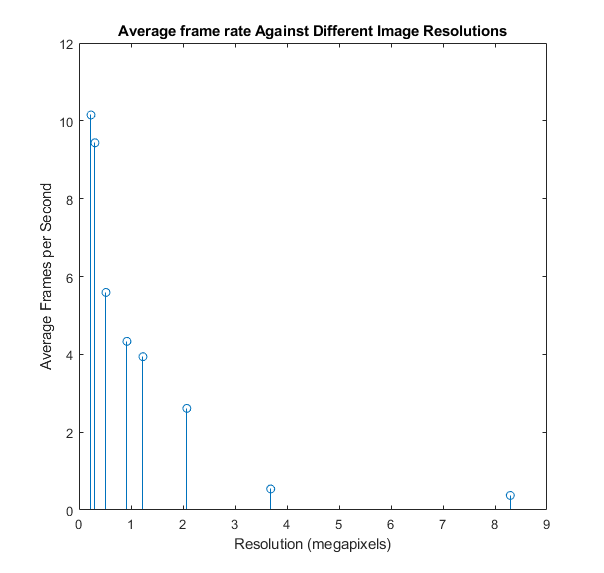

clear R; % we start by clearing the R variable from the memory, if it is there.
tic; % tic keyword is used to calculate the time of execution.
for k=1:1:10^8
 R(k)=rand(1);

end
toc % toc keyword is used to calculate the time of execution.
R

By doing different tries, It can be seen that it took about 17 seconds for the loop to end its execution.

Let us see the time it will take if we pre-allocate the array, R using the function ones(), so that its elements are initialized as 1s before entering the loop:

tic; % tic keyword is used to calculate the time of execution.
R=ones(1,10^8);
for k=1:10^8
 R(k)=rand(1);
end
toc % toc keyword is used to calculate the time of execution.

Elapsed time is 17.495172 seconds.


R

R =     0.7940    0.0866    0.4583    0.5840    0.8606    0.4653    0.2677    0.4028    0.4635    0.7045    0.3683    0.8711    0.0975    0.4232    0.6209    0.4480    0.4105    0.6103    0.9766    0.4694    0.6969    0.3113    0.6820    0.6362    0.8319    0.7279    0.7291    0.7710    0.0499    0.6052    0.5076    0.0485    0.6813    0.9889    0.8720    0.1302    0.5074    0.7127    0.6207    0.6403    0.1428    0.4310    0.6567    0.5030    0.9732    0.8146    0.9793    0.9050    0.3543    0.8008


By doing different tries, It can be seen that it took about 3.5 to 4.5 seconds for the loop to end its execution, which is less than the time it took when we did not pre-allocate the R array. Therefore, in our project, array pre-allocation was a practice followed so as to ensure time efficiency.

#### Vectorizing loops illustration

Vectorization in MATLAB refers to techniques for eliminating loops altogether, using a combination of matrix/vector operators, indexing techniques, and  existing MATLAB or toolbox functions. To illustrate this idea, we assume that we have an array, R, whose elements are random decimal numbers, ranging from 0 to 1. We want to threshold the elements of the array, such that the elements of R greater than or equal to 0.5 will be set to 1, and those less than 0.5 will be set to 0. By using a for loop, without vectorizing, our code will be written as given below (here the **tic **and **toc** keywords were used to time the execution time):

R=rand(1,10^7);
tic; % tic keyword is used to calculate the time of execution.
for k=1:10^7
    if (R(k) < 0.5)
        R(k) = 0;
    else

Elapsed time is 4.490343 seconds.


        R(k) = 1;

R =     0.6575    0.4060    0.9396    0.1912    0.2177    0.0114    0.9936    0.6470    0.3927    0.0140    0.0216    0.5640    0.5030    0.0753    0.6923    0.8079    0.6042    0.4873    0.6659    0.1948    0.2576    0.8163    0.6917    0.3877    0.5272    0.5269    0.1303    0.6193    0.2974    0.3550    0.0573    0.0205    0.5451    0.8404    0.5159    0.4526    0.3343    0.0376    0.0014    0.8907    0.5759    0.9953    0.0729    0.5312    0.6812    0.8870    0.3568    0.5464    0.0352    0.6040


    end
end
toc % toc keyword is used to calculate the time of execution.

By various experimentations, the loop took about 0.1 to 0.15 seconds to finish its execution.

Let us then see the time it will take if we vectorize the loop. The syntax of the loop will even look simpler, since it will take only operators to indicate the loop.

R=rand(1,10^7);
display("R array's variables before the loop execution")
R
tic; % tic keyword is used to calculate the time of execution.
R=(R >= 0.5);
toc % toc keyword is used to calculate the time of execution.
display("R array's variables after the loop execution")
double(R)

Elapsed time is 0.119271 seconds.


    "R array's variables before the loop execution"



R =     0.8910    0.6911    0.7243    0.1794    0.7174    0.4693    0.4250    0.8178    0.9972    0.2282    0.3039    0.8129    0.7015    0.5843    0.3700    0.8056    0.5461    0.7475    0.5680    0.7290    0.4101    0.4635    0.9536    0.1168    0.3076    0.9348    0.8828    0.2577    0.7380    0.4460    0.1268    0.0573    0.1606    0.7034    0.3709    0.1858    0.3840    0.7391    0.2153    0.8551    0.2314    0.8791    0.1065    0.6459    0.0043    0.9875    0.5681    0.1779    0.9253    0.1788


Elapsed time is 0.015905 seconds.


    "R array's variables after the loop execution"



ans =      1     1     1     0     1     0     0     1     1     0     0     1     1     1     0     1     1     1     1     1     0     0     1     0     0     1     1     0     1     0     0     0     0     1     0     0     0     1     0     1     0     1     0     1     0     1     1     0     1     0


Through various experimentation, the time of execution diminished to about 0.01 to 0.03 seconds. Therefore, in our project, loops vectorization was a practice followed so as to ensure time efficiency.

## The Graphical User Interface.

As it is was mentioned, this project aimed at developing a computer software for end-users. This means that the  image processing algorithms and functions explained above will be executed as the user  manipulates an interface that has graphics (buttons, plots of images, sliders, …). MATLAB has an application called “MATLAB App Designer” that allows to develop graphical user interfaces **[S. Attaway, in MATLAB: A practical introduction to programming and problem solving,  Oxford, United Kingdom: Elsevier, B/H, Butterworth-Heinemann, 2019, pp. 475–488.]**. MATLAB also allows to compile such graphical user interface software into  a standalone software for Windows and Mac Operating systems, through MATLAB Compiler **[R. Lee and R. Bachnak, “The Matlab Compiler Suite: M files to c/c++ executable  programs,” 2002 American Society for Engineering Education Annual Conference &  Exposition, p. 7.1164.2, 2002.]**. As we were investigating different ways of implementing the image processing  algorithms to be used in this project, we will also indicated some variables that the user  will be able to manipulate through the graphical user interface, depending on the output  he/she wishes. As it can be seen on the screenshot below, Those variables include the camera, the image trimmer sensitivity and the movement detector sensitivity.

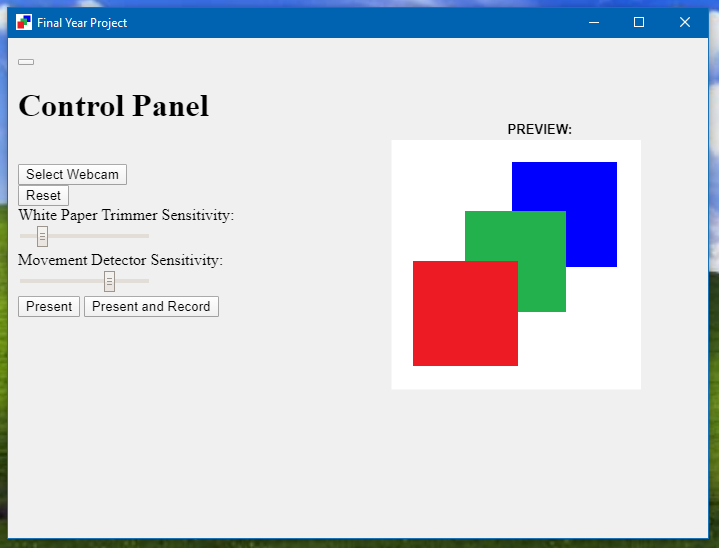

With the "Select Webcam" button, the user will be prompted to select an installed camera and available resolution and then preview a sample output of the camera on the "PREVIEW" pane. The image trimmer sensitivity slidebar indicate how much the user wants to trim the output video with respect to the white paper position. The movement detector sensitivity slidebar indicates how sensitive the system should be towards resetting in case the paper is moved with respect to the camera position.

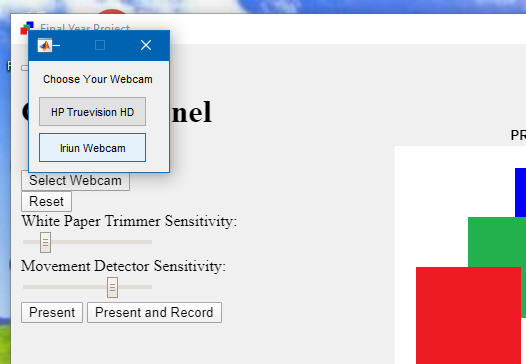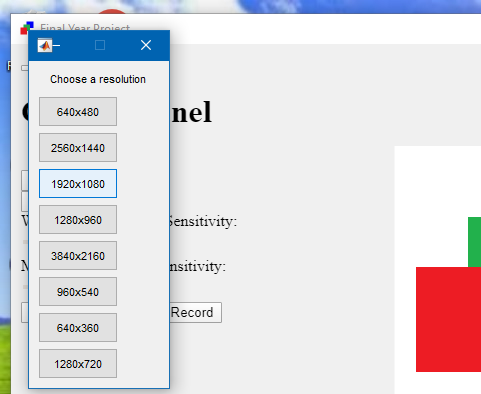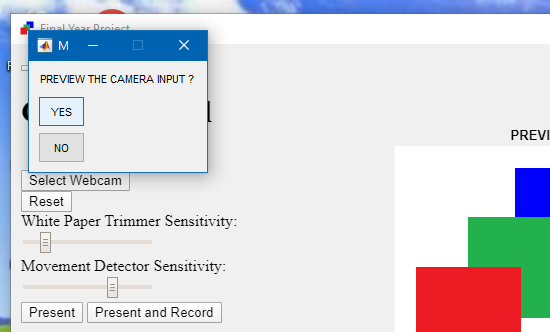

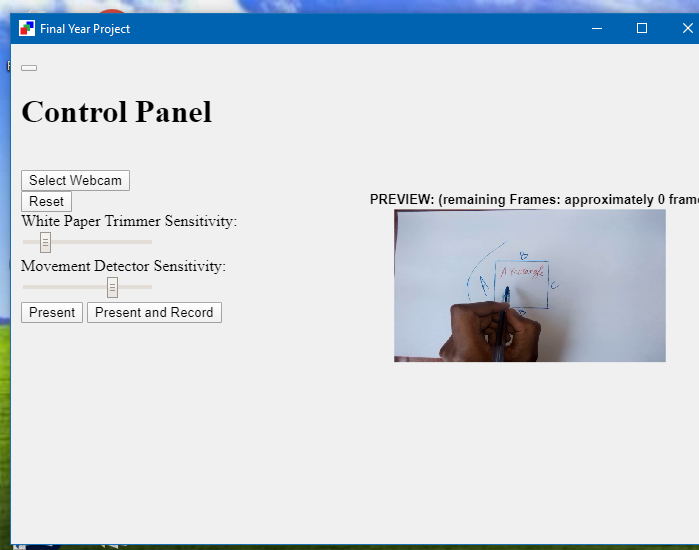

 Another feature that the final software possesses is the ability to record a video of  the processed frames. The software is able to record the video along with the audio. MATLAB has the VideoWriter object that allow to process digital images as video frames, select the frame rate and combine them  into a video file. MATLAB also has the audiorecorder object that can be used to record  audio and write it into a computer file. MATLAB also supports any kind of webcam  (camera) provided that it can be recognized by the computer’s operating system. The  webcamlist object shows a list of webcams connected to the computer, the webcam() and  snapshot() functions respectively, allow to select the webcam and to take photos instantly. On the graphical user interface we built, the user can choose to present the output and also recording the stream at the same time. The two buttons: "Present" and "Present and Record" allows to Only Present or Present and Record, respectively.

## Limitations of our system.

 The hypothesis of our research stated that “It is possible to implement a system that captures in real-time a video frames  sequence of pen strokes inscription on a white paper and simultaneously, processes  them into enhanced images, compensating for any pixel of the white paper obstructed  from the camera by a significant opaque object, thus neutralizing the obstruction”. The main expected result of this project was a graphical user interface software that will  capture image frames of a white paper as the writer is writing, and process the image frames  to show only the enhanced white paper and what is written on the paper (the pen strokes).  The system had to use segmentation processes to remove any part which is obstructing any  part of the white paper, including the writer’s hand. The system was expected also to allow the user to  record a video along with the audio, and the video will only be showing enhanced pen strokes being inscribing themselves on a purely white paper. While the result showed that most part of enhancement and obstruction removal matched the expectations, there are some few elements that did not comply with the hypothesis.

### The overal output is not appealing as expected.

The imperfect elegance of the output video frame is the first impression a user can see while manipulating our software. This is due to the fact that our system relies on a long sequence of image processing algorithms that include filtering out noises, detecting edges of pen strokes, sequences of morphological processes, etc. All those processes are for the purpose of protecting the thin pen strokes, while also removing the thinner noises, and the huge obstruction (the hand). Due to random fluctuations of illumination and noises that changes time by time and location by location, some details of pen strokes can disappear, and also unexpected noises may appear. Also by referring to the fact the system favours resolutions less than two megapixels (for the sake of preserving the frame rate, for a 2.4 GHz processor), the output video is not attractive, as we expected to extend up to 8 megapixels.

### The final software was not tested on various people with different skin color.

Due to the time limits, the final software was finished lately and thus it was tested on the group members who conducted this research. The only emulation that could be done was to turn the sides of the hand in front of camera, and see if the obstruction is removed. That emulation too did not work correctly as there are times the edge of the hand appeared due to light diffraction.

### The user should be aware about the camera's perspective with respect to the paper.

The user should know that if a region of the whiteboard is never exposed to the camera, the software will not be able to figure out the pen inscriptions from that region. It is recommended that the user should place the camera in a way that the line of sight from the camera to the whitepaper will not be obstructed most of the time. The user should also note that the system considers the first frame as a reference for removing the obstruction. Therefore, the user should not start presenting while the whitepaper is not fully exposed to the camera. This also applies to the case of resetting, when the paper is moved. The software was programmed to dim the intensity when the system resets due to paper movement or illumination changes. The user should remove his/her hand from the paper for about a second so as to ensure that the image processing loop resets correctly.

### Problems related to output video file compression.

MATLAB provides functions that allow to combine image frames into a video file, and other functions that allow a programmer to combine recorded audio samples into an audio file. When it came to combining the video frames together with audio samples into a single file, a compression challenge arose: the output file was extremely huge. We tried the two compressors available on the platform  ('DV Video Encoder' and 'MJPEG Compressor') **[https://www.mathworks.com/help/vision/ref/vision.videofilewriter-system-object.html]**, both did not provided a satisfactory performance, as a video of less that 10 seconds took more than 5 Megabytes, with a resolution lower than 240 pixels of width. Therefore, we concluded that the software will record a video and an audio separately, up to when a solution to the problem of compression will be discovered.

## Recommendation for Future Researches and Usages.

 As it was explained in the limitation section of this report, the overall output was not attractive as it was expected. This gives a task to anyone who may need to compliment our research to try different alternatives that can support high resolution images while also conserving the needed frame rate. This would require to use a computer with a more advanced processor so as to reduce the execution time. Another thing to consider while doing further researches is testing the system with various users of different skin color. This would give a more assurance of how the system is able to generalize and detect obstruction, or whether there are times people may need to wear dark gloves to ensure obstruction detection. Regarding the problem of re-adjusting the processed images sequence with  the change in position / perspective of the camera to the paper, we may recommend an implementation of geometric transformations, so as to re-align video frames whenever the paper is moved, and thus remove the obstruction easly. As the time did not allow us to tackle the problem of video file compression, we would also recommend future researches to consider developing or using other video compressing libraries different from those reported in the limitation section of this report. 

## Conclusion.

 The general objective of this project was to design and implement a software that would capture image frames of a white paper as the writer is writing, and process the image frames  to show only the enhanced white paper and what is written on the paper (the pen strokes). By refering to the presented report, it can be seen that the main tasks expressed in the main project were undertaken. Most of the part of this research project was related to programming, and also learning from different methods of image processing. The platform used for programming impacted the difficulty of the project, because it affected the speed of processing (as well as the frame rate), and the available video compressors. To ensure that the research schedule had to match with the researcher's academic calendar, some of the remaining challenges were not solved. Those challenges, as are reported in the "Limitations" section of this document, required refinement after testing the software in different conditions of noise and illuminations, and also on users with different skin colors. Future investigations to tackle those challenges are suggested for a more exhaustive research.